## 该代码为基于遗传算法神经网络的预测代码

清空环境变量

clc
clear
%

## 网络结构建立

%读取数据
load data input output

%节点个数
inputnum=2;
hiddennum=5;
outputnum=1;

%训练数据和预测数据
input_train=input(1:1900,:)';
input_test=input(1901:2000,:)';
output_train=output(1:1900)';
output_test=output(1901:2000)';

%选连样本输入输出数据归一化
[inputn,inputps]=mapminmax(input_train);
[outputn,outputps]=mapminmax(output_train);

%构建网络
net=newff(inputn,outputn,hiddennum);

## 遗传算法参数初始化

maxgen=20;                         %进化代数，即迭代次数
sizepop=10;                        %种群规模
pcross=[0.2];                       %交叉概率选择，0和1之间
pmutation=[0.1];                    %变异概率选择，0和1之间

%节点总数
numsum=inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum;

lenchrom=ones(1,numsum);        
bound=[-3*ones(numsum,1) 3*ones(numsum,1)];    %数据范围

## 种群初始化

individuals=struct('fitness',zeros(1,sizepop), 'chrom',[]);  %将种群信息定义为一个结构体
avgfitness=[];                      %每一代种群的平均适应度
bestfitness=[];                     %每一代种群的最佳适应度
bestchrom=[];                       %适应度最好的染色体
%初始化种群
for i=1:sizepop
    %随机产生一个种群
    individuals.chrom(i,:)=Code(lenchrom,bound);    %编码（binary和grey的编码结果为一个实数，float的编码结果为一个实数向量）
    x=individuals.chrom(i,:);
    %计算适应度
    individuals.fitness(i)=fun(x,inputnum,hiddennum,outputnum,net,inputn,outputn);   %染色体的适应度
end
FitRecord=[];
%找最好的染色体
[bestfitness bestindex]=min(individuals.fitness);
bestchrom=individuals.chrom(bestindex,:);  %最好的染色体
avgfitness=sum(individuals.fitness)/sizepop; %染色体的平均适应度
% 记录每一代进化中最好的适应度和平均适应度
trace=[avgfitness bestfitness];

## 迭代求解最佳初始阀值和权值

进化开始

for i=1:maxgen
    % 选择
    individuals=Select(individuals,sizepop); 
    avgfitness=sum(individuals.fitness)/sizepop;
    %交叉
    individuals.chrom=Cross(pcross,lenchrom,individuals.chrom,sizepop,bound);
    % 变异
    individuals.chrom=Mutation(pmutation,lenchrom,individuals.chrom,sizepop,i,maxgen,bound);
    
    % 计算适应度 
    for j=1:sizepop
        x=individuals.chrom(j,:); %解码
        individuals.fitness(j)=fun(x,inputnum,hiddennum,outputnum,net,inputn,outputn);   
    end
    
  %找到最小和最大适应度的染色体及它们在种群中的位置
    [newbestfitness,newbestindex]=min(individuals.fitness);
    [worestfitness,worestindex]=max(individuals.fitness);
    % 代替上一次进化中最好的染色体
    if bestfitness>newbestfitness
        bestfitness=newbestfitness;
        bestchrom=individuals.chrom(newbestindex,:);
    end
    individuals.chrom(worestindex,:)=bestchrom;
    individuals.fitness(worestindex)=bestfitness;
    
    avgfitness=sum(individuals.fitness)/sizepop;
    
    trace=[trace;avgfitness bestfitness]; %记录每一代进化中最好的适应度和平均适应度
    FitRecord=[FitRecord;individuals.fitness];
end

## 遗传算法结果分析

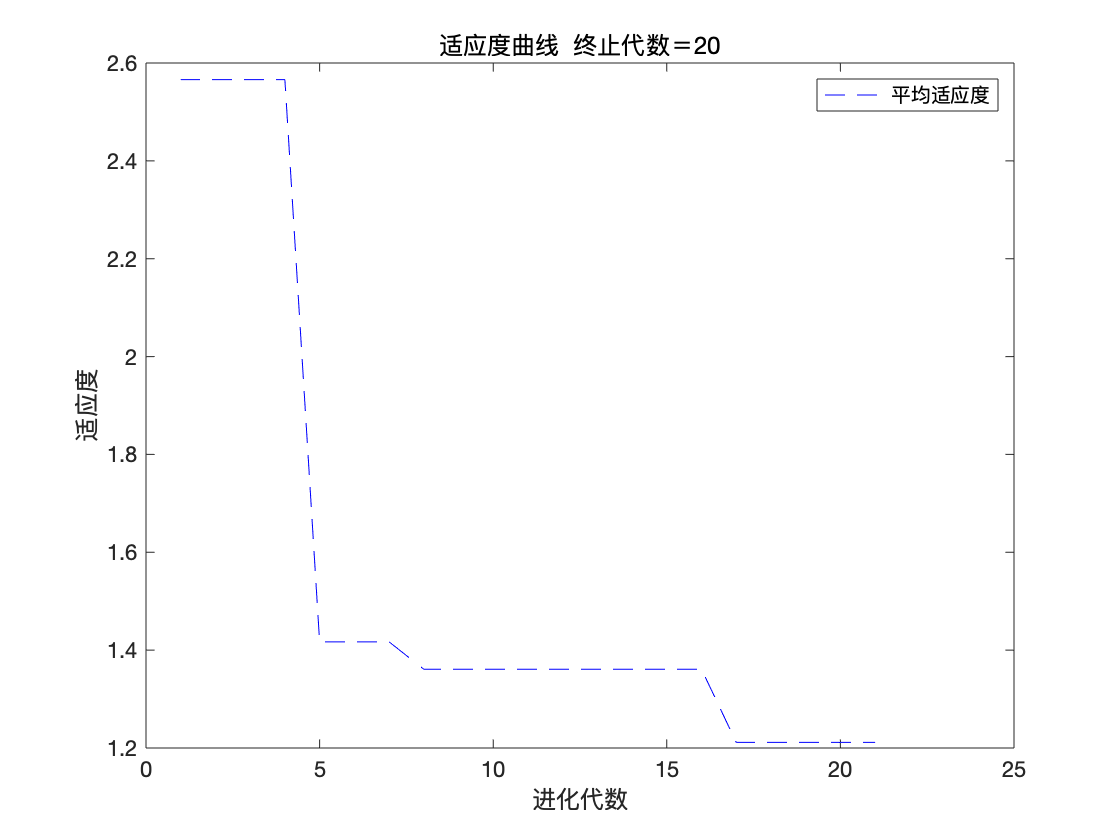

figure(1)
[r c]=size(trace);
plot([1:r]',trace(:,2),'b--');
title(['适应度曲线  ' '终止代数＝' num2str(maxgen)]);
xlabel('进化代数');ylabel('适应度');
legend('平均适应度');

## 把最优初始阀值权值赋予网络预测

%用遗传算法优化的BP网络进行值预测

w1=x(1:inputnum*hiddennum);
B1=x(inputnum*hiddennum+1:inputnum*hiddennum+hiddennum);
w2=x(inputnum*hiddennum+hiddennum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum);
B2=x(inputnum*hiddennum+hiddennum+hiddennum*outputnum+1:inputnum*hiddennum+hiddennum+hiddennum*outputnum+outputnum);

net.iw{1,1}=reshape(w1,hiddennum,inputnum);
net.lw{2,1}=reshape(w2,outputnum,hiddennum);
net.b{1}=reshape(B1,hiddennum,1);
net.b{2}=B2;

## BP网络训练

%网络进化参数
net.trainParam.epochs=100;
net.trainParam.lr=0.1;
%net.trainParam.goal=0.00001;

%网络训练
[net,per2]=train(net,inputn,outputn);

## BP网络预测

%数据归一化
inputn_test=mapminmax('apply',input_test,inputps);
an=sim(net,inputn_test);
test_simu=mapminmax('reverse',an,outputps);
error=test_simu-output_test;


## GA优化BP网络预测结果分析

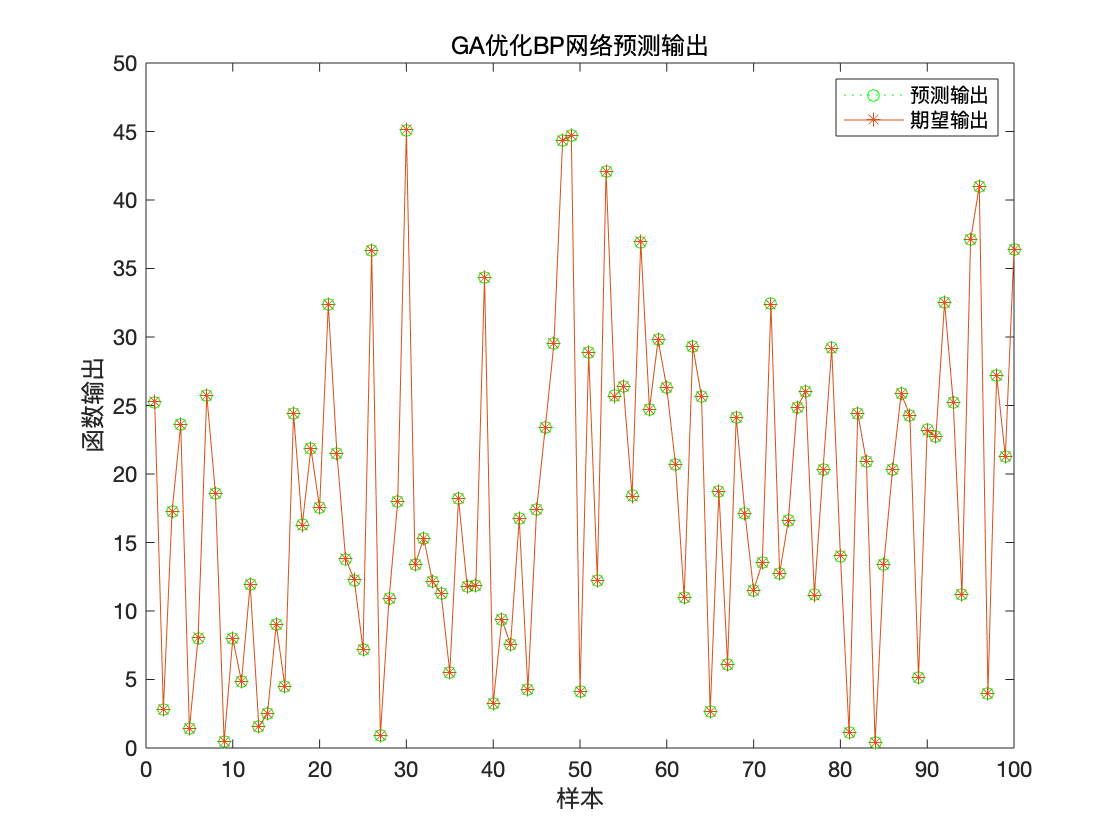

figure(2)
plot(test_simu,':og')
hold on
plot(output_test,'-*');
legend('预测输出','期望输出')
title('GA优化BP网络预测输出','fontsize',12)
ylabel('函数输出','fontsize',12)
xlabel('样本','fontsize',12)

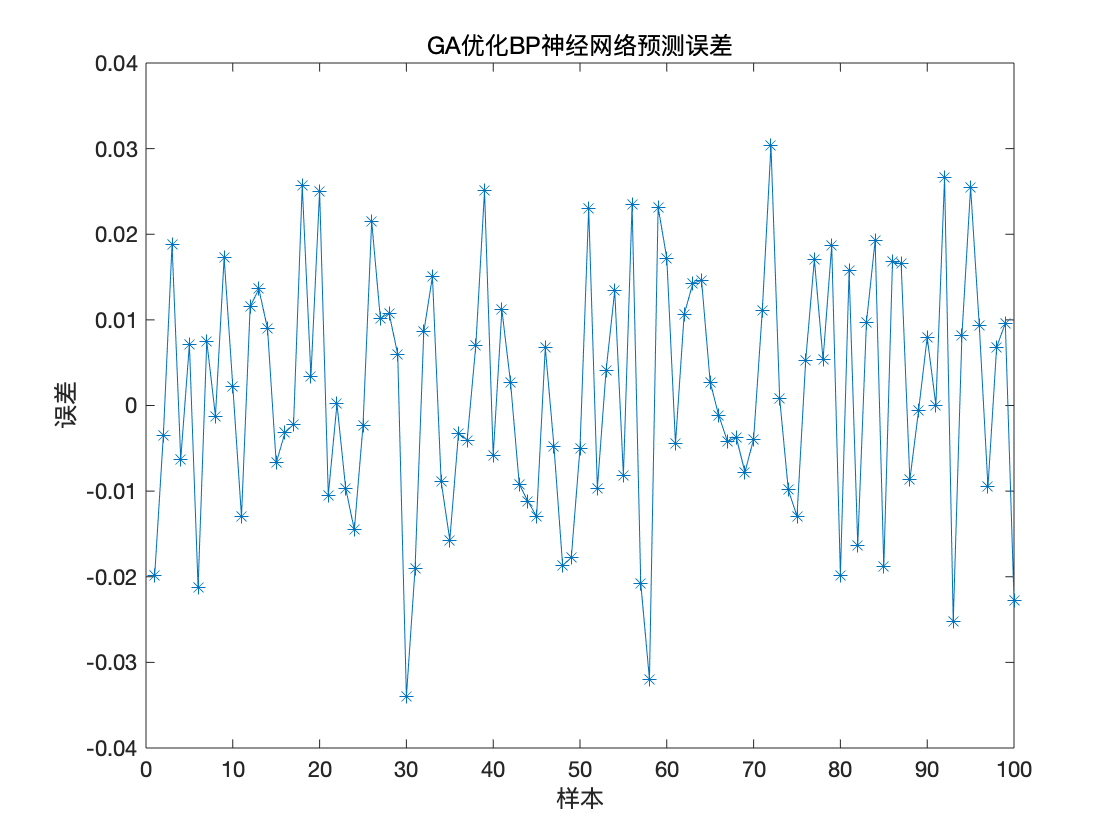

%预测误差
error=test_simu-output_test;
figure(3)
plot(error,'-*')
title('GA优化BP神经网络预测误差','fontsize',12)
ylabel('误差','fontsize',12)
xlabel('样本','fontsize',12)

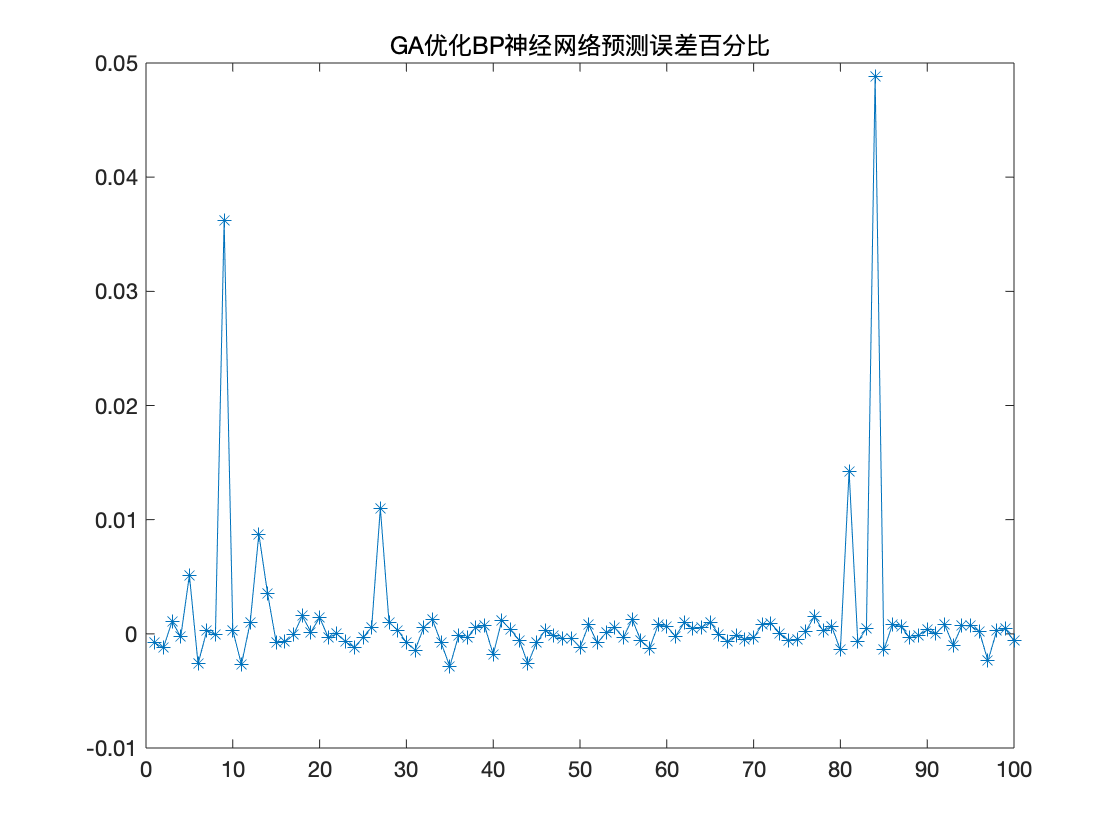

figure(4)
plot((test_simu-output_test)./output_test,'-*');
title('GA优化BP神经网络预测误差百分比')

errorsum=sum(abs(error));